## Analysis of fixed points and stability of the nonlinear difference equation model for social mobilization. 

The model is described in detail in chapter 3 of Huckfeldt, Kohfeld, & Likens (1982).

∆M = g(L - Mt) + s*Mt*[(L-Mt) – g(L-Mt)]– fMt

- where g is the probability (or rate) of gaining members within time step

- f is the probability (or rate) of loosing members within time step

- L is the proportion of people in the population that are “mobilizable”

- s - social interaction term

Standard form:

Mt+1 = (sg-s)*Mt2 + (1+sL – f – g – sgL)*Mt + gL

## Fixed points:

% Define symbolic function f(x) and symbolic variable x
syms f(x) g f L s

f(x) = (s*g-s)*x^2+(1+s*L-f-g-s*g*L)*x+g*L; 

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the symbolic expression for the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);
fp

$$fp = \begin{array}{l} \left(\begin{array}{c} -\frac{f+g-\sigma_{1}-L\,s+L\,g\,s}{2\,\left(s-g\,s\right)}\\ -\frac{f+g+\sigma_{1}-L\,s+L\,g\,s}{2\,\left(s-g\,s\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{L^{2}\,g^{2}\,s^{2}-2\,L^{2}\,g\,s^{2}+L^{2}\,s^{2}+2\,L\,f\,g\,s-2\,L\,f\,s-2\,L\,g^{2}\,s+2\,L\,g\,s+f^{2}+2\,f\,g+g^{2}} \end{array}$$

The model has a single fixed point as expected for a linear model.

## Stability analysis:

Standard form for a first-order difference equation is : Mt+1 = a0 + a1*Mt + a2*Mt^2.

Our model in standard form: Mt+1 = (sg-s)*Mt^2+(1+s*L-f-g-sgL)*Mt+gL ,where **a****0 = ****gL, a****1 = (1+sL-f-g-sgL), and a2 = sg-s**

syms f(x) g f L s
g_in = 0.16;
f_in = 0.34;
L_in = 1;
s_in = 0.54;

% substitute specific values of g, f, and L parameters into the model
f(x) = subs((s*g-s)*x^2+(1+s*L-f-g-s*g*L)*x+g*L,{g,f,L,s},[g_in,f_in,L_in,s_in]);

% Find derivative of f(x) - rate of change of this fuction - slope of f(x)
fd(x) = diff(f(x));

% Find the symbolic expression for the fixed points -- points where f(x) is equal to x
fp = solve(f(x)==x);

% Convert fixed points from symbolic to numeric variable for plotting
fp_num = double(fp);
fp_num

fp_num =    -0.6473
    0.5450



% substitue the values of the fixed points into the derivative function to
% get the slope of f(x) at the fixed points
m = subs(fd(fp_num));
m_num = double(m)

m_num =     1.5408
    0.4592



% Classify fixed points
stable_fp = abs(m_num)<1;
unstable_fp = abs(m_num)>1;

% Plot the function and the fixed points
figure
fplot(f(x),[0 1])
hold

Current plot held


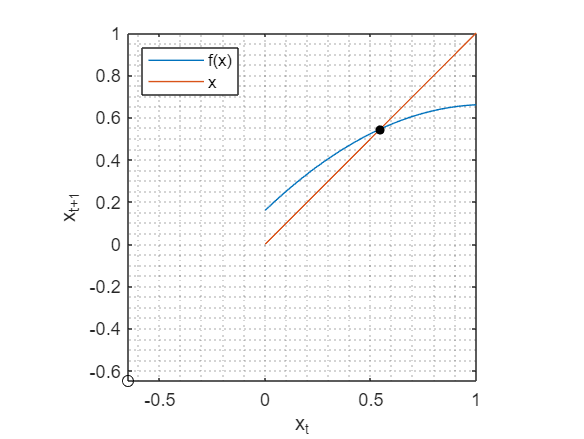

fplot(x,[0 1])

% Next line plots the location of the fixed point as (x,y) coordinate. x = fp value, y = f(fp)
plot(fp_num(unstable_fp),f(fp_num(unstable_fp)),'ok') % Unstable fixed points
plot(fp_num(stable_fp),f(fp_num(stable_fp)),'.k','markersize',15) % Stable fixed points
grid minor
axis square
ylabel('x_{t+1}')
xlabel('x_t')
legend('f(x)','x','Location','Northwest')

## Numerical simulation of the model

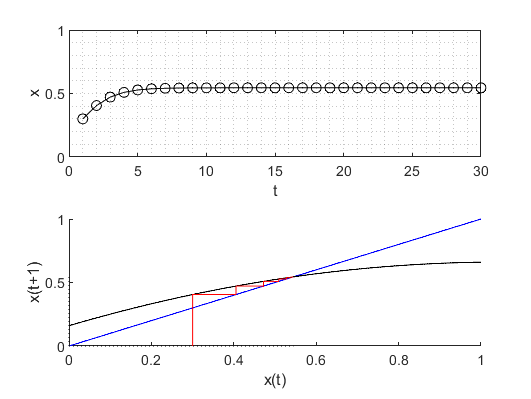

[xt] = NonLinearSocialMobilization(0.3, g_in, f_in, L_in, s_in, 30, .25);

## Project idea:

Similar to the linear model: Apply this model to one of the poll data time series from [https://fivethirtyeight.com/.](https://fivethirtyeight.com) Which model is better at predicting future poll values? Which one fits the available data better? What would be your criterion for model evaluation?

Procedure to estimate parameter values:

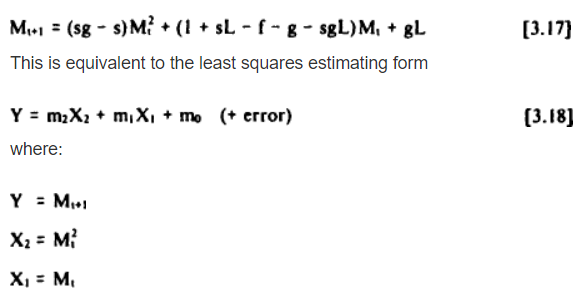

Then, the coefficients of the linear model estimates with ordinary least squares are equal to:

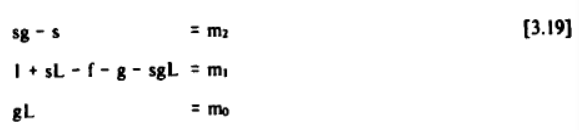

Then, making an assumption that L = 1, we get:

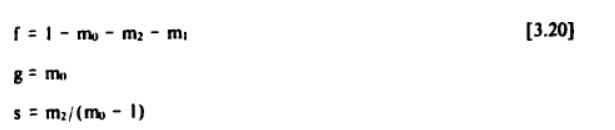

So, the estimate of L parameter is crucial because all other parameters depend on it. The mobilizable proportion of the population, L, has to be done from other available sources.